## 作业2:

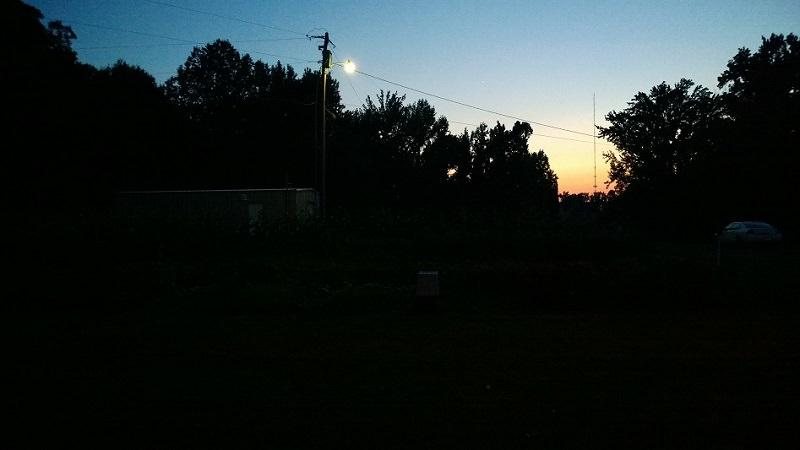

•**对上述低照度图像进行灰度化，计算并显示以上低照度图像的****灰度直方图****和****离散傅里叶变换频谱幅度图****；**

•**对以上低照度图像分别进行****直方图均衡化****和****同态滤波****操作，并对两种算法的最终效果进行对比；**

•**代码注释****不少于40%；**

### 灰度直方图与DFT幅度图显示

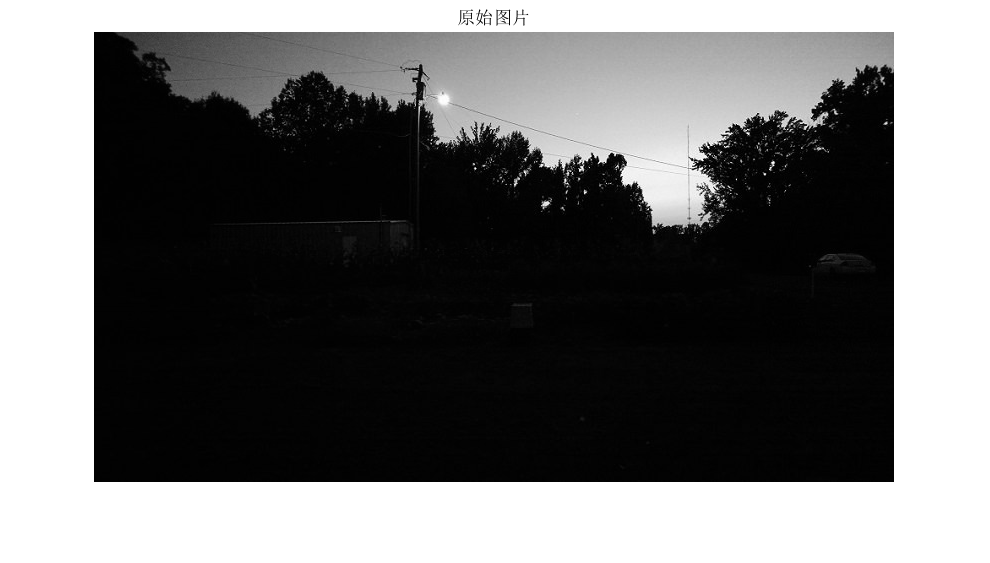

img=imread('fig.jpg'); %读入原图像
img=im2double(rgb2gray(img)); %将图象数组转换成double精度类型
figure;%先开一张图, 不然下面两个subplot会把这个顶掉
imshow(img);
title('原始图片');

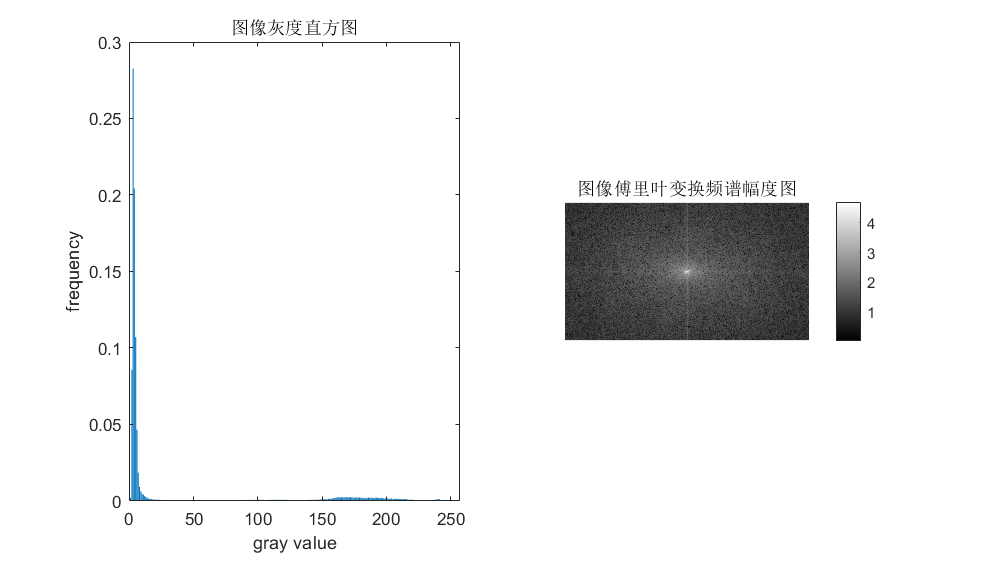


%显示直方图
subplot(1,2,1);
h=img_hist(img);
title('图像灰度直方图');

%显示离散傅里叶变换频谱图
%ft_shift(img);%将频率原点移至中心点
F=ft2(ft_shift(img));
imF=log10(abs(F)+1);%取个对数, 压缩一下数的范围
subplot(1,2,2);
imshow(imF,[])%[]会把结果映射到01区间内
colormap gray
colorbar
title('图像傅里叶变换频谱幅度图');

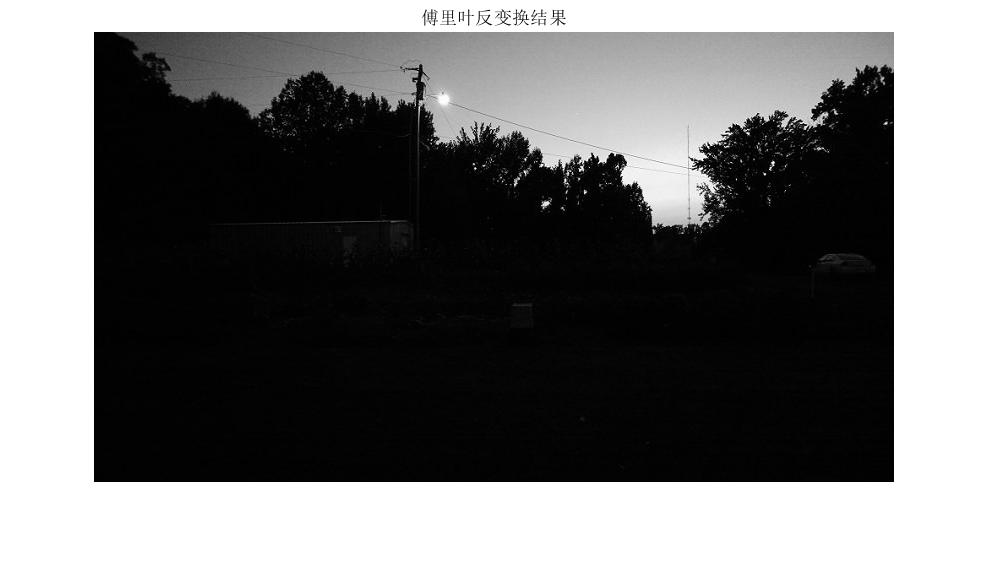


f=ift2(F);
imf=abs(ft_shift(f));%不取绝对值会使报错, 无法同时画实部跟虚部
figure;
imshow(imf);
title('傅里叶反变换结果')

### 直方图均衡化

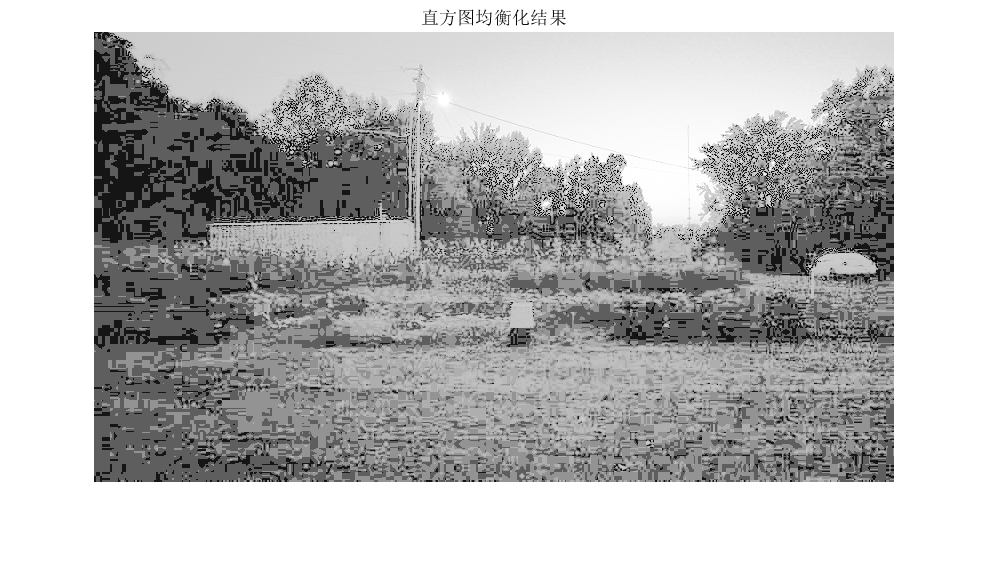

new_img=histgram_equalization(img,h);
figure;
imshow(new_img,[]);%加上[], 把结果映射一下
title('直方图均衡化结果');

### 同态滤波

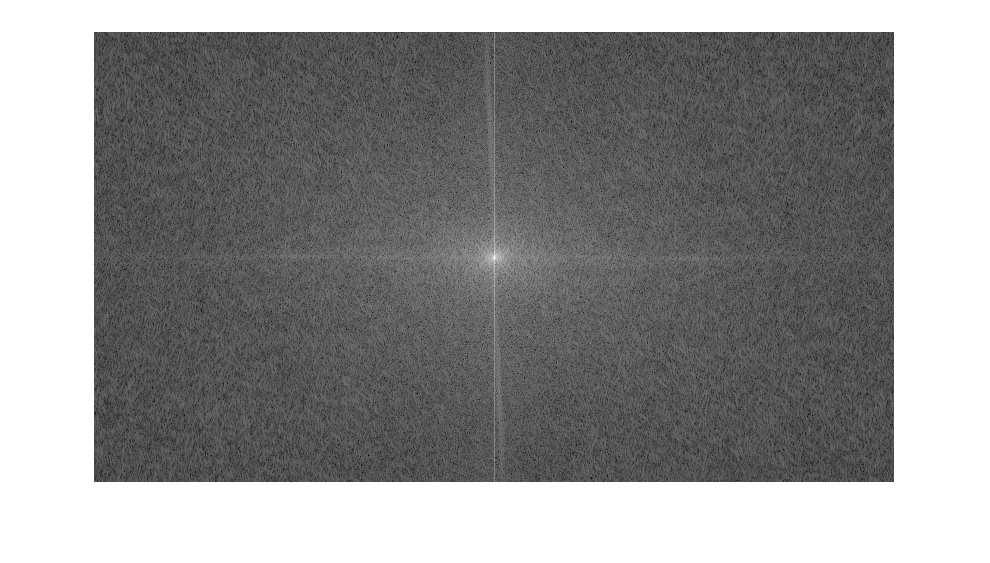

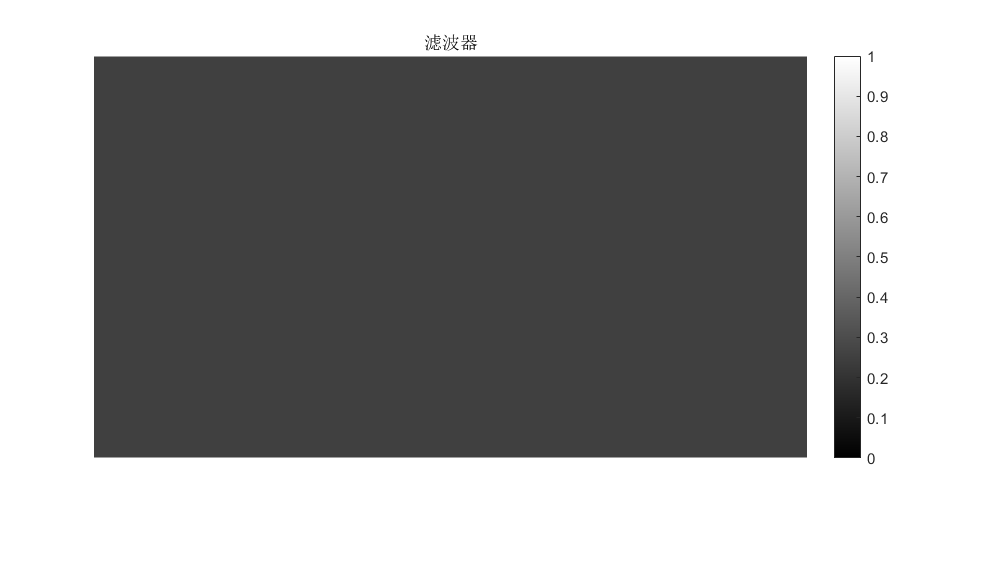

new_img=homofilter(img,1000,2);%二分之一频率点要取大一点, 不然结果图被锐化程度很深

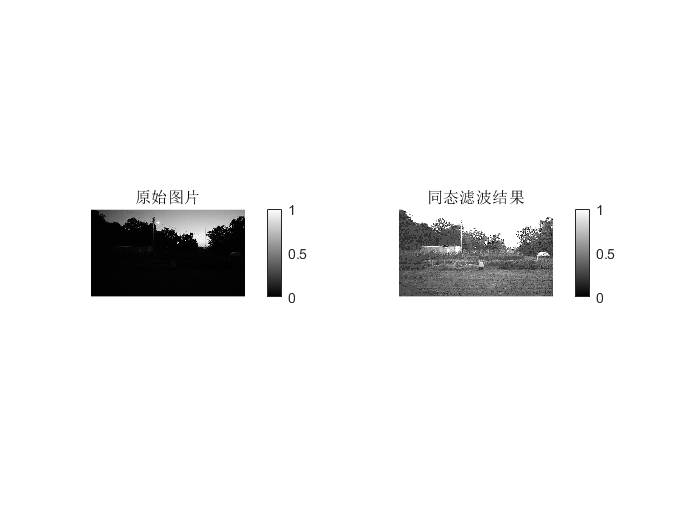


figure;%新开一张图
subplot(1,2,1);
imshow(img,[]);
colorbar
title('原始图片')

subplot(1,2,2);
imshow(new_img);
colormap gray
colorbar
title('同态滤波结果');

# 结论:

对比两种滤波的结果可以看出, 同态滤波的结果比直方图均衡化的结果更好, 不过从结果图来看, 同态滤波的结果图也存在着振铃现象影响, 局部图像变糊了(也可能是参数调的还不够好.....)